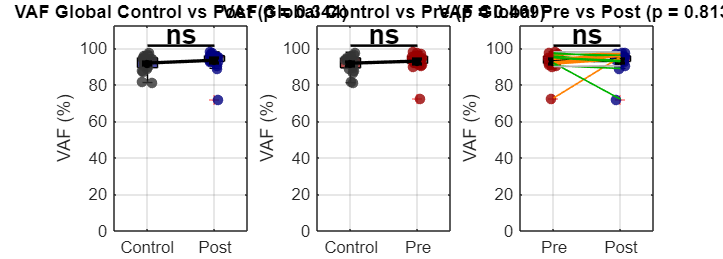

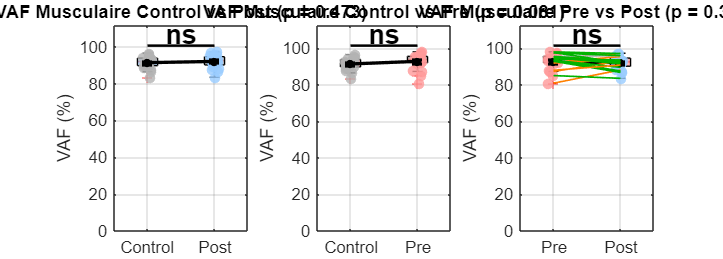


----- VAF Global Control vs Post -----


N: Groupe 1 = 20, Groupe 2 = 20


Moyenne (±SEM): Control = 91.85 (±1.02), Post = 93.38 (±1.23)


Test de normalité (Shapiro-Wilk): Control p=1.0000, Post p=1.0000


Test d'homogénéité des variances: p=0.4340 (Homogènes)


Test paramétrique (t-test (var. égales)): p=0.3443


Test non paramétrique (Mann-Whitney): p=0.0909


Test final utilisé (t-test (var. égales)): p=0.3443 non significatif


Taille d'effet (d de Cohen): 0.30 (effet faible)



----- VAF Global Control vs Pre -----


N: Groupe 1 = 20, Groupe 2 = 20


Moyenne (±SEM): Control = 91.85 (±1.02), Pre = 92.99 (±1.19)


Test de normalité (Shapiro-Wilk): Control p=1.0000, Pre p=1.0000


Test d'homogénéité des variances: p=0.5324 (Homogènes)


Test paramétrique (t-test (var. égales)): p=0.4694


Test non paramétrique (Mann-Whitney): p=0.2616


Test final utilisé (t-test (var. égales)): p=0.4694 non significatif


Taille d'effet (d de Cohen): 0.23 (effet faible)



----- VAF Global Pre vs Post -----


N: Groupe 1 = 20, Groupe 2 = 20


Moyenne (±SEM): Pre = 92.99 (±1.19), Post = 93.38 (±1.23)


Test de normalité (Shapiro-Wilk): Pre p=1.0000, Post p=1.0000


Test paramétrique (t-test apparié): p=0.8133


Test non paramétrique (Wilcoxon): p=0.6813


Test final utilisé (t-test apparié): p=0.8133 non significatif


Taille d'effet (d de Cohen): 0.05 (effet négligeable)



----- VAF Musculaire Control vs Post -----


N: Groupe 1 = 20, Groupe 2 = 20


Moyenne (±SEM): Control = 91.40 (±0.73), Post = 92.09 (±0.81)


Test de normalité (Shapiro-Wilk): Control p=0.0000, Post p=0.0000


Test d'homogénéité des variances: p=0.6772 (Homogènes)


Test paramétrique (t-test (var. égales)): p=0.5341


Test non paramétrique (Mann-Whitney): p=0.4735


Test final utilisé (Mann-Whitney): p=0.4735 non significatif


Taille d'effet (d de Cohen): 0.20 (effet négligeable)



----- VAF Musculaire Control vs Pre -----


N: Groupe 1 = 20, Groupe 2 = 20


Moyenne (±SEM): Control = 91.40 (±0.73), Pre = 92.84 (±0.98)


Test de normalité (Shapiro-Wilk): Control p=0.0000, Pre p=1.0000


Test d'homogénéité des variances: p=0.2128 (Homogènes)


Test paramétrique (t-test (var. égales)): p=0.2472


Test non paramétrique (Mann-Whitney): p=0.0810


Test final utilisé (Mann-Whitney): p=0.0810 non significatif


Taille d'effet (d de Cohen): 0.37 (effet faible)



----- VAF Musculaire Pre vs Post -----


N: Groupe 1 = 20, Groupe 2 = 20


Moyenne (±SEM): Pre = 92.84 (±0.98), Post = 92.09 (±0.81)


Test de normalité (Shapiro-Wilk): Pre p=1.0000, Post p=0.0000


Test paramétrique (t-test apparié): p=0.3831


Test non paramétrique (Wilcoxon): p=0.3135


Test final utilisé (Wilcoxon): p=0.3135 non significatif


Taille d'effet (d de Cohen): -0.20 (effet négligeable)


%% Comparaison des VAF globaux et musculaires entre groupes
% Script amélioré avec couleurs personnalisées, visualisations avancées et tableau récapitulatif

%% Définition des couleurs personnalisées
dark_black = [0.2, 0.2, 0.2];   % Control VAF_G
light_black = [0.7, 0.7, 0.7];  % Control VAF_M
dark_red = [0.6, 0, 0];         % Pre VAF_G
light_red = [1.0, 0.6, 0.6];    % Pre VAF_M
dark_blue = [0, 0, 0.5];        % Post VAF_G
light_blue = [0.6, 0.8, 1.0];   % Post VAF_M

% Couleurs pour les changements (tests appariés)
color_increase = [1.0, 0.5, 0.0]; % Orange pour augmentation
color_decrease = [0.0, 0.7, 0.0]; % Vert pour diminution
color_no_change = [0.7, 0.7, 0.7]; % Gris pour pas de changement

%% Chargement des données
VAF = ComparaisonVAF;

% Extraction des colonnes
VAF_global_asympt = VAF(:,1);
VAF_musculaire_asympt = VAF(:,2) * 100; % Multiplication par 100
VAF_global_preop = VAF(:,3);
VAF_musculaire_preop = VAF(:,4) * 100; % Multiplication par 100
VAF_global_postop = VAF(:,5);
VAF_musculaire_postop = VAF(:,6) * 100; % Multiplication par 100

%% Configuration des comparaisons à effectuer
comparaisons = {
    struct('groupe1', VAF_global_asympt, 'groupe2', VAF_global_postop, 'type', 'indep', 'titre', 'VAF Global Control vs Post', 'label1', 'Control', 'label2', 'Post', 'color1', dark_black, 'color2', dark_blue)
    struct('groupe1', VAF_global_asympt, 'groupe2', VAF_global_preop, 'type', 'indep', 'titre', 'VAF Global Control vs Pre', 'label1', 'Control', 'label2', 'Pre', 'color1', dark_black, 'color2', dark_red)
    struct('groupe1', VAF_global_preop, 'groupe2', VAF_global_postop, 'type', 'paired', 'titre', 'VAF Global Pre vs Post', 'label1', 'Pre', 'label2', 'Post', 'color1', dark_red, 'color2', dark_blue)
    struct('groupe1', VAF_musculaire_asympt, 'groupe2', VAF_musculaire_postop, 'type', 'indep', 'titre', 'VAF Musculaire Control vs Post', 'label1', 'Control', 'label2', 'Post', 'color1', light_black, 'color2', light_blue)
    struct('groupe1', VAF_musculaire_asympt, 'groupe2', VAF_musculaire_preop, 'type', 'indep', 'titre', 'VAF Musculaire Control vs Pre', 'label1', 'Control', 'label2', 'Pre', 'color1', light_black, 'color2', light_red)
    struct('groupe1', VAF_musculaire_preop, 'groupe2', VAF_musculaire_postop, 'type', 'paired', 'titre', 'VAF Musculaire Pre vs Post', 'label1', 'Pre', 'label2', 'Post', 'color1', light_red, 'color2', light_blue)
};

% Initialisation du tableau récapitulatif
resultats_tableau = {};
header = {'Comparaison', 'Type', 'N1', 'N2', 'Moyenne1', 'SEM1', 'Moyenne2', 'SEM2', 'Normal1', 'Normal2', 'VarHomog', 'Test_Final', 'p_value', 'Significatif', 'Cohen_d', 'Effet'};
resultats_tableau{1, 1} = header;

% Créer des figures pour VAF global et musculaire
figure('Name', 'Comparaisons VAF Global', 'Position', [100, 100, 1400, 500], 'Color', 'white');
figure('Name', 'Comparaisons VAF Musculaire', 'Position', [100, 600, 1400, 500], 'Color', 'white');

%% Boucle sur les comparaisons
for i = 1:length(comparaisons)
    data1 = comparaisons{i}.groupe1;
    data2 = comparaisons{i}.groupe2;
    type = comparaisons{i}.type;
    titre = comparaisons{i}.titre;
    label1 = comparaisons{i}.label1;
    label2 = comparaisons{i}.label2;
    color1 = comparaisons{i}.color1;
    color2 = comparaisons{i}.color2;
    
    % Suppression des NaN
    nan_idx = isnan(data1) | isnan(data2);
    data1_clean = data1(~nan_idx);
    data2_clean = data2(~nan_idx);
    
    % Calcul des statistiques descriptives
    n1 = length(data1_clean);
    n2 = length(data2_clean);
    mean1 = mean(data1_clean);
    mean2 = mean(data2_clean);
    std1 = std(data1_clean);
    std2 = std(data2_clean);
    sem1 = std1/sqrt(n1);
    sem2 = std2/sqrt(n2);
    
    % Test de normalité avec Shapiro-Wilk
    [sw_p1, sw_h1] = swtest(data1_clean);
    [sw_p2, sw_h2] = swtest(data2_clean);
    is_normal = sw_p1 >= 0.05 && sw_p2 >= 0.05;
    
    % Test d'homogénéité des variances si groupes indépendants
    if strcmp(type, 'indep')
        [~, p_var] = vartest2(data1_clean, data2_clean);
        var_equal = p_var >= 0.05;
    else
        p_var = NaN; % pas pertinent pour paired
        var_equal = true; % non utilisé pour paired
    end
    
    % Calcul de la taille d'effet (d de Cohen)
    if strcmp(type, 'paired')
        d_cohen = mean(data2_clean - data1_clean) / std(data2_clean - data1_clean);
    else
        pooled_std = sqrt(((n1 - 1) * std1^2 + (n2 - 1) * std2^2) / (n1 + n2 - 2));
        d_cohen = abs(mean1 - mean2) / pooled_std;
    end
    
    % Réalisation des tests statistiques appropriés
    % Tests paramétriques
    if strcmp(type, 'paired')
        [h_ttest, p_ttest] = ttest(data1_clean, data2_clean);
        test_param = 't-test apparié';
    else
        if var_equal
            [h_ttest, p_ttest] = ttest2(data1_clean, data2_clean, 'Vartype', 'equal');
            test_param = 't-test (var. égales)';
        else
            [h_ttest, p_ttest] = ttest2(data1_clean, data2_clean, 'Vartype', 'unequal');
            test_param = 't-test Welch (var. inégales)';
        end
    end
    
    % Tests non paramétriques
    if strcmp(type, 'paired')
        [p_nonpar, h_nonpar] = signrank(data1_clean, data2_clean);
        test_nonpar = 'Wilcoxon';
    else
        [p_nonpar, h_nonpar] = ranksum(data1_clean, data2_clean);
        test_nonpar = 'Mann-Whitney';
    end
    
    % Choix du test final en fonction de la normalité
    if is_normal
        p_final = p_ttest;
        test_final = test_param;
    else
        p_final = p_nonpar;
        test_final = test_nonpar;
    end
    
    % Remplissage du tableau récapitulatif
    resultats_tableau{i+1, 1} = titre;
    resultats_tableau{i+1, 2} = type;
    resultats_tableau{i+1, 3} = n1;
    resultats_tableau{i+1, 4} = n2;
    resultats_tableau{i+1, 5} = round(mean1, 2);
    resultats_tableau{i+1, 6} = round(sem1, 2);
    resultats_tableau{i+1, 7} = round(mean2, 2);
    resultats_tableau{i+1, 8} = round(sem2, 2);
    resultats_tableau{i+1, 9} = sw_p1 >= 0.05;
    resultats_tableau{i+1, 10} = sw_p2 >= 0.05;
    if ~isnan(p_var)
        resultats_tableau{i+1, 11} = p_var >= 0.05;
    else
        resultats_tableau{i+1, 11} = 'N/A';
    end
    resultats_tableau{i+1, 12} = test_final;
    resultats_tableau{i+1, 13} = round(p_final, 4);
    resultats_tableau{i+1, 14} = p_final < 0.05;
    resultats_tableau{i+1, 15} = round(d_cohen, 2);
    resultats_tableau{i+1, 16} = interpretCohenD(d_cohen);
    
    % Affichage des résultats
    fprintf('\n----- %s -----\n', titre);
    fprintf('N: Groupe 1 = %d, Groupe 2 = %d\n', n1, n2);
    fprintf('Moyenne (±SEM): %s = %.2f (±%.2f), %s = %.2f (±%.2f)\n', label1, mean1, sem1, label2, mean2, sem2);
    fprintf('Test de normalité (Shapiro-Wilk): %s p=%.4f, %s p=%.4f\n', label1, sw_p1, label2, sw_p2);
    
    if ~isnan(p_var)
        if var_equal
            fprintf('Test d\''homogénéité des variances: p=%.4f (Homogènes)\n', p_var);
        else
            fprintf('Test d\''homogénéité des variances: p=%.4f (Hétérogènes)\n', p_var);
        end
    end
    
    fprintf('Test paramétrique (%s): p=%.4f\n', test_param, p_ttest);
    fprintf('Test non paramétrique (%s): p=%.4f\n', test_nonpar, p_nonpar);
    if p_final < 0.05
        fprintf('Test final utilisé (%s): p=%.4f **SIGNIFICATIF**\n', test_final, p_final);
    else
        fprintf('Test final utilisé (%s): p=%.4f non significatif\n', test_final, p_final);
    end
    fprintf('Taille d''effet (d de Cohen): %.2f (%s)\n', d_cohen, interpretCohenD(d_cohen));
    
    % Choix de la figure appropriée (1 pour global, 2 pour musculaire)
    if contains(titre, 'Global')
        figure_num = 1;
    else
        figure_num = 2;
    end
    
    % Visualisation avec subplot pour organiser les comparaisons
    figure(figure_num);
    subplot(1, 3, mod(i-1, 3)+1);
    
    % Créer d'abord un boxplot avec les couleurs personnalisées
    boxplot_data = [data1_clean; data2_clean];
    boxplot_groups = [ones(size(data1_clean)); 2*ones(size(data2_clean))];
    h_box = boxplot(boxplot_data, boxplot_groups, 'Labels', {label1, label2});
    
    % Personnaliser les couleurs du boxplot
    box_colors = [color1; color2];
    h = findobj(gca,'Tag','Box');
    for j = 1:length(h)
        patch(get(h(j),'XData'), get(h(j),'YData'), box_colors(j,:), 'FaceAlpha', 0.7);
    end
    
    hold on;
    
    % Ajouter les points individuels (scatter) avec les bonnes couleurs
    scatter(ones(size(data1_clean))*1 + (rand(size(data1_clean))-0.5)*0.15, data1_clean, 40, color1, 'filled', 'MarkerFaceAlpha', 0.8);
    scatter(ones(size(data2_clean))*2 + (rand(size(data2_clean))-0.5)*0.15, data2_clean, 40, color2, 'filled', 'MarkerFaceAlpha', 0.8);
    
    % Ajouter la moyenne et l'erreur standard
    errorbar([1, 2], [mean1, mean2], [sem1, sem2], 'k.', 'LineWidth', 2, 'MarkerSize', 15);
    
    % Ligne noire reliant les moyennes
    plot([1, 2], [mean1, mean2], '-k', 'LineWidth', 2);
    
    % Ajouter des lignes colorées pour les données appariées
    if strcmp(type, 'paired')
        for j = 1:length(data1_clean)
            diff_val = data2_clean(j) - data1_clean(j);
            if abs(diff_val) < 0.5  % Seuil pour "aucun changement"
                line_color = color_no_change;
            elseif diff_val > 0
                line_color = color_increase;
            else
                line_color = color_decrease;
            end
            plot([1, 2], [data1_clean(j), data2_clean(j)], '-', 'Color', line_color, 'LineWidth', 1);
        end
    end
    
    % Ajout p-valeur et astérisques pour la significativité
    y_max = max([data1_clean; data2_clean]) * 1.15;
    if p_final < 0.001
        sig_text = '***';
    elseif p_final < 0.01
        sig_text = '**';
    elseif p_final < 0.05
        sig_text = '*';
    else
        sig_text = 'ns';
    end
    
    % Ajouter une barre entre les groupes et le texte de significativité
    plot([1, 2], [y_max*0.9, y_max*0.9], '-k', 'LineWidth', 1.5);
    text(1.5, y_max*0.95, sig_text, 'HorizontalAlignment', 'center', 'FontSize', 16, 'FontWeight', 'bold');
    
    ylabel('VAF (%)', 'FontSize', 12);
    title(sprintf('%s (p = %.3f)', titre, p_final), 'FontSize', 11, 'Interpreter', 'none');
    ylim([0, y_max]);
    set(gca, 'Color', 'white');
    grid on;
    box on;
    set(gca, 'FontSize', 10);
end


%% Sauvegarde du tableau récapitulatif
% Tentative Excel d'abord
try
    writecell(resultats_tableau, 'Resultats_VAF_Recapitulatif.xlsx');
    fprintf('\n✓ Tableau récapitulatif sauvegardé dans "Resultats_VAF_Recapitulatif.xlsx"\n');
catch
    % Si Excel échoue, essayer CSV
    try
        % Conversion en format compatible CSV
        csv_data = resultats_tableau;
        % Remplacer les valeurs logiques par du texte
        for i = 1:size(csv_data, 1)
            for j = 1:size(csv_data, 2)
                if islogical(csv_data{i,j})
                    if csv_data{i,j}
                        csv_data{i,j} = 'Oui';
                    else
                        csv_data{i,j} = 'Non';
                    end
                end
            end
        end
        
        % Créer un fichier CSV
        fid = fopen('Resultats_VAF_Recapitulatif.csv', 'w');
        for i = 1:size(csv_data, 1)
            for j = 1:size(csv_data, 2)
                if j == size(csv_data, 2)
                    fprintf(fid, '%s\n', string(csv_data{i,j}));
                else
                    fprintf(fid, '%s;', string(csv_data{i,j}));
                end
            end
        end
        fclose(fid);
        fprintf('\n✓ Tableau récapitulatif sauvegardé dans "Resultats_VAF_Recapitulatif.csv"\n');
    catch
        fprintf('\n⚠ Impossible de sauvegarder le fichier. Affichage du tableau formaté:\n');
        
        % Affichage formaté du tableau
        fprintf('\n====== RÉSULTATS RÉCAPITULATIFS VAF ======\n');
        fprintf('%-35s | %-8s | %-3s | %-3s | %-7s | %-6s | %-7s | %-6s | %-6s | %-6s | %-9s | %-20s | %-8s | %-6s | %-7s | %-15s\n', ...
            'Comparaison', 'Type', 'N1', 'N2', 'Moy1', 'SEM1', 'Moy2', 'SEM2', 'Norm1', 'Norm2', 'VarHom', 'Test', 'p-value', 'Signif', 'Cohen_d', 'Effet');
        fprintf('%s\n', repmat('-', 1, 180));
        
        for i = 2:size(resultats_tableau, 1)
            fprintf('%-35s | %-8s | %-3d | %-3d | %-7.2f | %-6.2f | %-7.2f | %-6.2f | %-6s | %-6s | %-9s | %-20s | %-8.4f | %-6s | %-7.2f | %-15s\n', ...
                resultats_tableau{i,1}, resultats_tableau{i,2}, resultats_tableau{i,3}, resultats_tableau{i,4}, ...
                resultats_tableau{i,5}, resultats_tableau{i,6}, resultats_tableau{i,7}, resultats_tableau{i,8}, ...
                iif(resultats_tableau{i,9}, 'Oui', 'Non'), iif(resultats_tableau{i,10}, 'Oui', 'Non'), ...
                iif(strcmp(resultats_tableau{i,11}, 'N/A'), 'N/A', iif(resultats_tableau{i,11}, 'Oui', 'Non')), ...
                resultats_tableau{i,12}, resultats_tableau{i,13}, iif(resultats_tableau{i,14}, 'Oui', 'Non'), ...
                resultats_tableau{i,15}, resultats_tableau{i,16});
        end
        fprintf('%s\n', repmat('=', 1, 180));
    end
end


✓ Tableau récapitulatif sauvegardé dans "Resultats_VAF_Recapitulatif.csv"


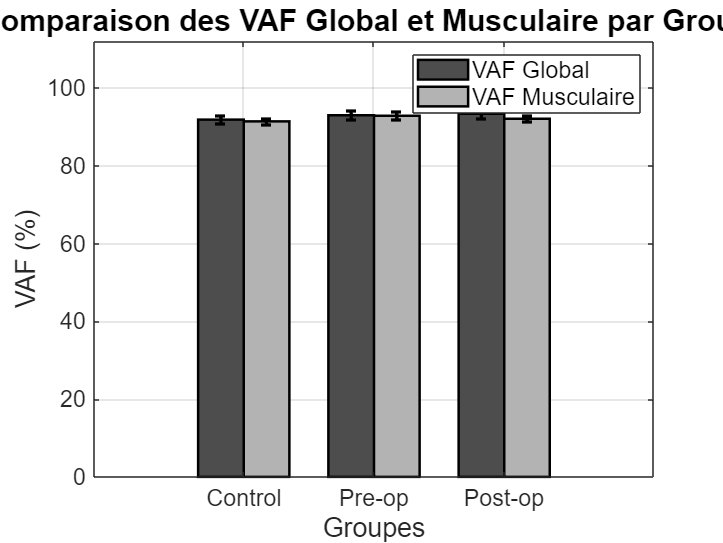


% GRAPHIQUES SUPPLEMENTAIRES POUR LE MEMOIRE

%% Graphique 1: Vue d'ensemble des moyennes avec barres d'erreur
figure('Name', 'Vue d''ensemble VAF - Graphique Mémoire 1', 'Position', [200, 100, 800, 600], 'Color', 'white');

% Données pour le graphique en barres groupées
categories = {'Control', 'Pre-op', 'Post-op'};
VAF_global_means = [mean(VAF_global_asympt, 'omitnan'), mean(VAF_global_preop, 'omitnan'), mean(VAF_global_postop, 'omitnan')];
VAF_musculaire_means = [mean(VAF_musculaire_asympt, 'omitnan'), mean(VAF_musculaire_preop, 'omitnan'), mean(VAF_musculaire_postop, 'omitnan')];

VAF_global_sem = [std(VAF_global_asympt, 'omitnan')/sqrt(sum(~isnan(VAF_global_asympt))), ...
                  std(VAF_global_preop, 'omitnan')/sqrt(sum(~isnan(VAF_global_preop))), ...
                  std(VAF_global_postop, 'omitnan')/sqrt(sum(~isnan(VAF_global_postop)))];
VAF_musculaire_sem = [std(VAF_musculaire_asympt, 'omitnan')/sqrt(sum(~isnan(VAF_musculaire_asympt))), ...
                      std(VAF_musculaire_preop, 'omitnan')/sqrt(sum(~isnan(VAF_musculaire_preop))), ...
                      std(VAF_musculaire_postop, 'omitnan')/sqrt(sum(~isnan(VAF_musculaire_postop)))];

% Création du graphique en barres
x = 1:length(categories);
width = 0.35;

bar1 = bar(x - width/2, VAF_global_means, width, 'FaceColor', [0.3, 0.3, 0.3], 'EdgeColor', 'k', 'LineWidth', 1.5);
hold on;
bar2 = bar(x + width/2, VAF_musculaire_means, width, 'FaceColor', [0.7, 0.7, 0.7], 'EdgeColor', 'k', 'LineWidth', 1.5);

% Ajout des barres d'erreur
errorbar(x - width/2, VAF_global_means, VAF_global_sem, 'k', 'LineStyle', 'none', 'LineWidth', 2);
errorbar(x + width/2, VAF_musculaire_means, VAF_musculaire_sem, 'k', 'LineStyle', 'none', 'LineWidth', 2);

% Personnalisation
set(gca, 'XTick', x, 'XTickLabel', categories, 'FontSize', 14, 'Color', 'white');
ylabel('VAF (%)', 'FontSize', 16);
xlabel('Groupes', 'FontSize', 16);
title('Comparaison des VAF Global et Musculaire par Groupe', 'FontSize', 18, 'FontWeight', 'bold');
legend({'VAF Global', 'VAF Musculaire'}, 'Location', 'northeast', 'FontSize', 14);
grid on;
ylim([0, max([VAF_global_means, VAF_musculaire_means]) * 1.2]);

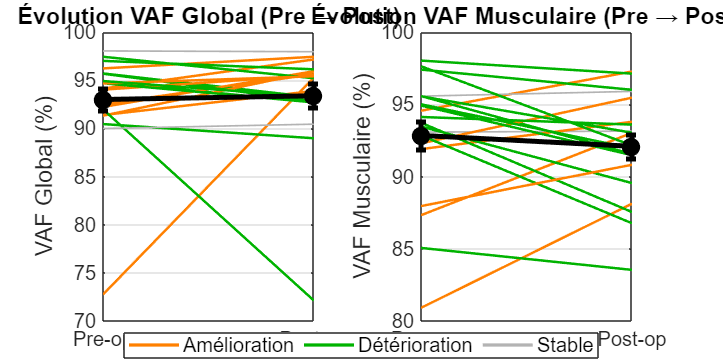


%% Graphique 2: Évolution Pre-Post avec lignes individuelles
figure('Name', 'Évolution Pre-Post VAF - Graphique Mémoire 2', 'Position', [300, 200, 1000, 500], 'Color', 'white');

% Subplot pour VAF Global
subplot(1, 2, 1);
% Supprimer les NaN pour les données appariées
valid_idx_global = ~isnan(VAF_global_preop) & ~isnan(VAF_global_postop);
pre_global_clean = VAF_global_preop(valid_idx_global);
post_global_clean = VAF_global_postop(valid_idx_global);

% Tracé des lignes individuelles avec couleurs selon l'évolution
for i = 1:length(pre_global_clean)
    diff_val = post_global_clean(i) - pre_global_clean(i);
    if abs(diff_val) < 0.5
        line_color = color_no_change;
        line_width = 1;
    elseif diff_val > 0
        line_color = color_increase;
        line_width = 1.5;
    else
        line_color = color_decrease;
        line_width = 1.5;
    end
    plot([1, 2], [pre_global_clean(i), post_global_clean(i)], '-', 'Color', line_color, 'LineWidth', line_width);
    hold on;
end

% Ajout des moyennes avec barres d'erreur
mean_pre_global = mean(pre_global_clean);
mean_post_global = mean(post_global_clean);
sem_pre_global = std(pre_global_clean)/sqrt(length(pre_global_clean));
sem_post_global = std(post_global_clean)/sqrt(length(post_global_clean));

errorbar([1, 2], [mean_pre_global, mean_post_global], [sem_pre_global, sem_post_global], 'ko-', 'LineWidth', 3, 'MarkerSize', 8, 'MarkerFaceColor', 'k');

set(gca, 'XTick', [1, 2], 'XTickLabel', {'Pre-op', 'Post-op'}, 'FontSize', 12, 'Color', 'white');
ylabel('VAF Global (%)', 'FontSize', 14);
title('Évolution VAF Global (Pre → Post)', 'FontSize', 14, 'FontWeight', 'bold');
grid on;

% Subplot pour VAF Musculaire
subplot(1, 2, 2);
% Supprimer les NaN pour les données appariées
valid_idx_musc = ~isnan(VAF_musculaire_preop) & ~isnan(VAF_musculaire_postop);
pre_musc_clean = VAF_musculaire_preop(valid_idx_musc);
post_musc_clean = VAF_musculaire_postop(valid_idx_musc);

% Tracé des lignes individuelles avec couleurs selon l'évolution
for i = 1:length(pre_musc_clean)
    diff_val = post_musc_clean(i) - pre_musc_clean(i);
    if abs(diff_val) < 0.5
        line_color = color_no_change;
        line_width = 1;
    elseif diff_val > 0
        line_color = color_increase;
        line_width = 1.5;
    else
        line_color = color_decrease;
        line_width = 1.5;
    end
    plot([1, 2], [pre_musc_clean(i), post_musc_clean(i)], '-', 'Color', line_color, 'LineWidth', line_width);
    hold on;
end

% Ajout des moyennes avec barres d'erreur
mean_pre_musc = mean(pre_musc_clean);
mean_post_musc = mean(post_musc_clean);
sem_pre_musc = std(pre_musc_clean)/sqrt(length(pre_musc_clean));
sem_post_musc = std(post_musc_clean)/sqrt(length(post_musc_clean));

errorbar([1, 2], [mean_pre_musc, mean_post_musc], [sem_pre_musc, sem_post_musc], 'ko-', 'LineWidth', 3, 'MarkerSize', 8, 'MarkerFaceColor', 'k');

set(gca, 'XTick', [1, 2], 'XTickLabel', {'Pre-op', 'Post-op'}, 'FontSize', 12, 'Color', 'white');
ylabel('VAF Musculaire (%)', 'FontSize', 14);
title('Évolution VAF Musculaire (Pre → Post)', 'FontSize', 14, 'FontWeight', 'bold');
grid on;

% Légende commune
han = axes('visible', 'off');
han.Title.Visible = 'on';
han.XLabel.Visible = 'on';
han.YLabel.Visible = 'on';
hold(han, 'on');
h1 = plot(han, NaN, NaN, '-', 'Color', color_increase, 'LineWidth', 2);
h2 = plot(han, NaN, NaN, '-', 'Color', color_decrease, 'LineWidth', 2);
h3 = plot(han, NaN, NaN, '-', 'Color', color_no_change, 'LineWidth', 2);
legend(han, [h1, h2, h3], {'Amélioration', 'Détérioration', 'Stable'}, ...
       'Position', [0.45, 0.02, 0.1, 0.05], 'Orientation', 'horizontal', 'FontSize', 12);


fprintf('\n✓ Graphiques supplémentaires créés pour le mémoire\n');


✓ Graphiques supplémentaires créés pour le mémoire


fprintf('  - Graphique 1: Vue d''ensemble avec barres groupées\n');

  - Graphique 1: Vue d'ensemble avec barres groupées


fprintf('  - Graphique 2: Évolution Pre-Post avec codage couleur\n');

  - Graphique 2: Évolution Pre-Post avec codage couleur
